## **Nombres: **

- **Jorge Fernando Bustos Mendez (221160068)**

- **Nicolas Narvaez Arturo (221160075)**

# **Gráficas hechas con la función plot**

Primera ecuación en diferencia

close all; clc;
syms z;
k = 0 : 0.01 : 60 ;
fz = z*(((1/16)/(z-3))+((-1/16)/(z+1))+((-1/4)/(z+1)^2))

$$fz = -z\,\left(\frac{1}{16\,\left(z+1\right)}+\frac{1}{4\,{\left(z+1\right)}^{2}}-\frac{1}{16\,\left(z-3\right)}\right)$$

fk = iztrans (fz,k);
y = fk;
plot(k,y, 'g')

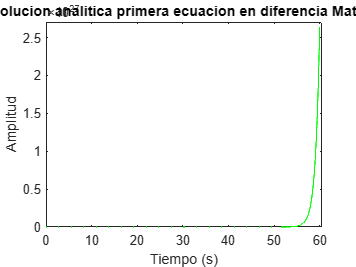

title("Solucion analitica primera ecuacion en diferencia Matlab")
xlabel("Tiempo (s)")
ylabel("Amplitud")
xlim([0 60.5])
ylim([-0.1 2705306875721805248350650368])

Segunda ecuación en diferencia

syms z;
k = 0 : 0.01 : 90 ;
fz = z*(((((-1/871)*z)+(-29/871))/(z^2-z+1))+((1/871/(z-30))))

$$fz = -z\,\left(\frac{\frac{z}{871}+\frac{29}{871}}{z^{2}-z+1}-\frac{1}{871\,\left(z-30\right)}\right)$$

fk = iztrans (fz,k);
y = fk;
plot(k,y, 'm')

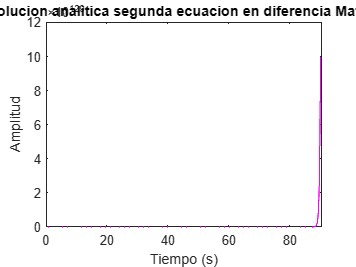

title("Solucion analitica segunda ecuacion en diferencia Matlab")
xlabel("Tiempo (s)")
ylabel("Amplitud")
xlim([0 90.5])
ylim([0 12026257745627346338473046158961254569594549325997992959253466906097219967524236870581046516557528420332053925814476202730003103744])

# **Gráficas hechas con la función step**

Primera ecuación en diferencia

n = [1 0];
d = [1 -1 -5 -3];
g = tf(n,d,1)

g =
 
           z
  -------------------
  z^3 - z^2 - 5 z - 3
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


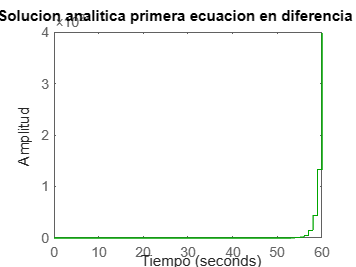

step(g, 'g')
title("Solucion analitica primera ecuacion en diferencia Matlab")
xlabel("Tiempo")
ylabel("Amplitud")

Segunda ecuación en diferencia

n = [1 0];
d = [1 -31 31 -30];
g = tf(n,d,1)

g =
 
             z
  ------------------------
  z^3 - 31 z^2 + 31 z - 30
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


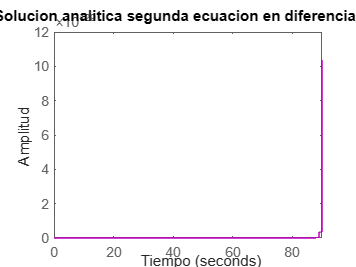

step(g, 'm')
title("Solucion analitica segunda ecuacion en diferencia Matlab")
xlabel("Tiempo")
ylabel("Amplitud")